# Vacchini Edoardo 467102

Partendo dai dati puliti si può ora partire con la fase di identificazione del modello. Questa verrà fatta considerando i seguenti modelli:

- **Modello cubico**: si tratta di un modello di riferimento del caso. Si spezza l'intervallo di dati in 3 e si identifica un modello cubico per l'intervallo tra la *cut-in wind speed* e la *cut-out wind speed*, ovvero dove non è presente la saturazione. 

- **Modello a doppio esponenziale**: prende in considerazione la curva fino alla cutout speed.

- **Funzione logistica**: grazie alla sua forma a sigmoide si potrebbe prestarsi bene

Per prima cosa preparo i dati di identificazione e quelli di validazione spezzando in due il dataset e imposto il dizionario per avere una struttura dati che contenga tutti gli indici per la validazione e scelta del modello.

clc; clear; close all;
turbines = readtable('clean_dataset.csv');

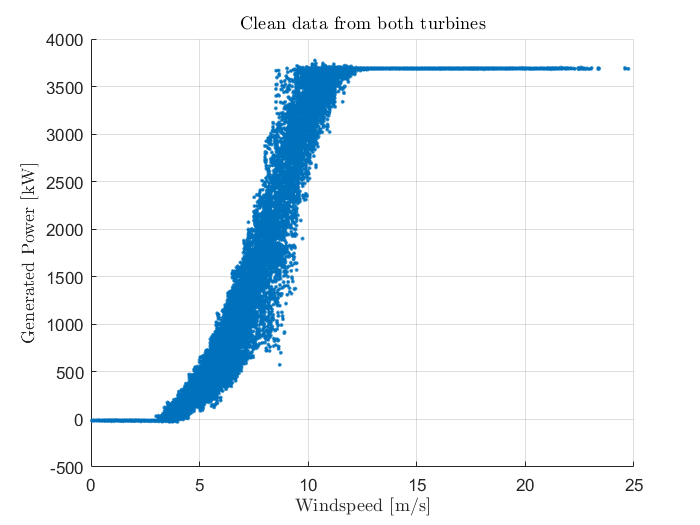

figure;
scatter(turbines.windspeed, turbines.power, '.');
grid on;
title('Clean data from both turbines', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Generated Power [kW]', "Interpreter", 'latex');

Spezzo il dataset in due set, uno di training e uno di validazione.

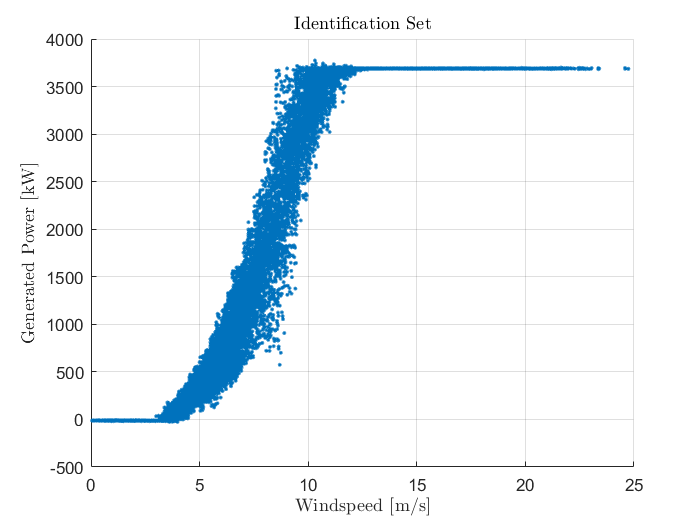

trainingPercentage = 0.8;

trainingSet = turbines(randperm(size(turbines, 1), floor(trainingPercentage * size(turbines, 1))), :);
validationSet = setdiff(turbines, trainingSet);

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
grid on;
title('Identification Set', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Generated Power [kW]', "Interpreter", 'latex');

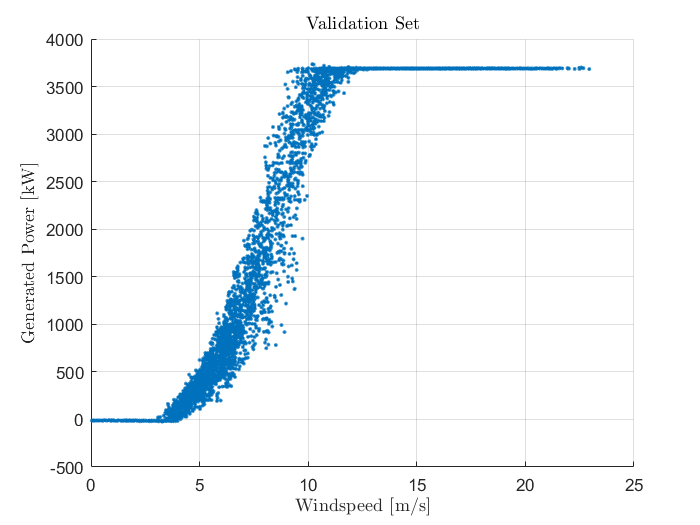


figure;
scatter(validationSet.windspeed, validationSet.power, '.');
grid on;
title('Validation Set', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Generated Power [kW]', "Interpreter", 'latex');

### Modello Benchmark

Il modello benchmark è costuito da una semplice funzione cubica nell'intervallo incluso tra le velocità di *cut-in* e di *cut-out*.


$$P\left(v\right)=\frac{1}{2}\rho {\;}_{\textrm{air}} A\;v^{3\;}$$


Dove $\rho_{\textrm{air}}$ è la densità dell'aria e $A$ è l'area della spazzata, ovvero la superficie coperta dalla pala di raggio $r=65m$.

cutin_windspeed = 3;
cutout_windspeed = 12;

datainrange = trainingSet(trainingSet.windspeed > cutin_windspeed & trainingSet.windspeed <= cutout_windspeed, :);
[theta, sigma] = lscov(datainrange.windspeed.^3, datainrange.power);
Y_Hat = datainrange.windspeed.^3 * theta;

Nella sezione di saturazione per completare il modello su tutto l'intervallo di velocità del vento, uso il valore medio delle saturazioni vere e lo applico da quando la curva cubica supera il livello di saturazione;

saturationValue = mean(trainingSet(trainingSet.windspeed > 12,:).power);

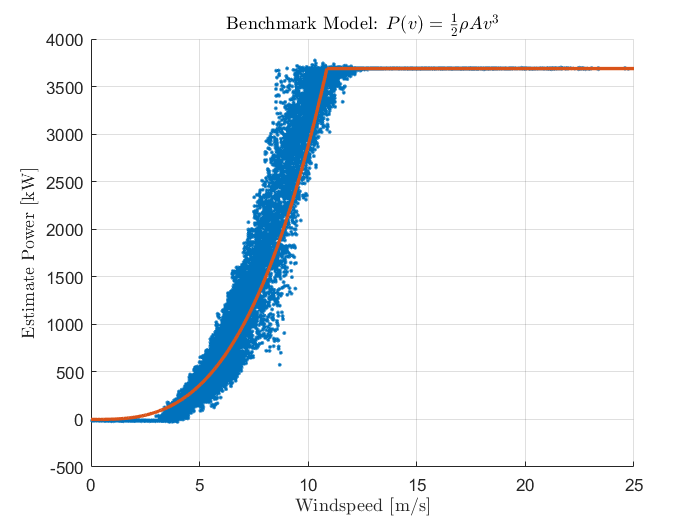

density = 0.01;
saturationWindspeed = density * floor(((saturationValue / theta) ^ (1/3))*(1/density));
windspeedGrid = [0 : density : 25]';

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
grid on;
plot(windspeedGrid, benchmark_model(windspeedGrid, theta, saturationWindspeed, saturationValue), "LineWidth", 2);
title('Benchmark Model: $P(v) = \frac{1}{2}\rho Av^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

Le predizioni sui dati di validazione:

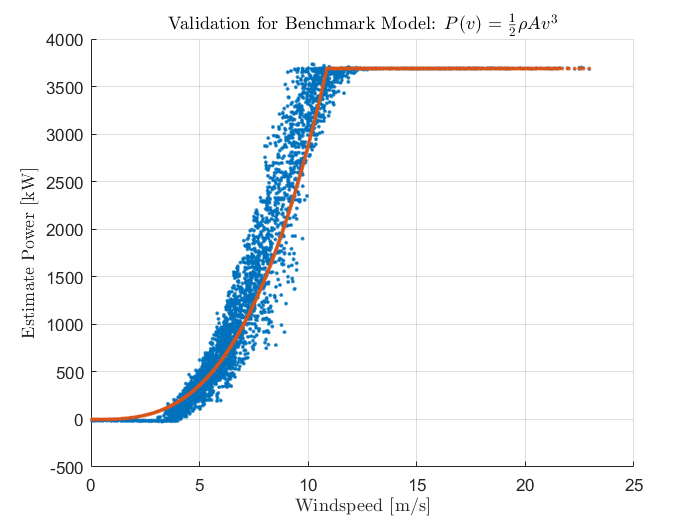

Y_Hat_validation = benchmark_model(validationSet.windspeed, theta, saturationWindspeed, saturationValue);

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
grid on;
scatter(validationSet.windspeed, Y_Hat_validation, '.');
title('Validation for Benchmark Model: $P(v) = \frac{1}{2}\rho Av^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

benchmarkModel.parameters = theta;
benchmarkModel.standardDeviation = sigma;
benchmarkModel.MSE = (1/length(Y_Hat)) * sum((datainrange.power - Y_Hat).^2);
benchmarkModel.SSR = sum((datainrange.power - Y_Hat).^2);
benchmarkModel.FPE = ((length(Y_Hat) + length(theta))/(length(Y_Hat) - length(theta))) * benchmarkModel.SSR ;
benchmarkModel.AIC = (2*length(theta) / length(Y_Hat)) * log(sum((datainrange.power - Y_Hat).^2));
benchmarkModel.MDL = (log(length(Y_Hat))*length(theta) / length(Y_Hat)) * log(sum((datainrange.power - Y_Hat).^2));
benchmarkModel.ValidationSSR = sum((validationSet.power - Y_Hat_validation).^2);
benchmarkModel.WMAPE = sum(abs(validationSet.power - Y_Hat_validation))/sum(abs(validationSet.power));
benchmarkModel.NRMSE = sqrt(benchmarkModel.MSE / (max(validationSet.power) - min(validationSet.power)));

### Modelli cubici

Un modello di riferimento è quello cubico, con cui si modellizza il tratto crescente con un modello:


$$P\left(v\right)=\theta_1 +\theta_2 v+\theta_3 v^{2\;} +\theta_4 v^3$$


cutin_windspeed = 1.5;
cutout_windspeed = 12.5;

datainrange = trainingSet(trainingSet.windspeed < cutout_windspeed & trainingSet.windspeed > cutin_windspeed, :);

PHI = [ones(length(datainrange.windspeed), 1), datainrange.windspeed, datainrange.windspeed.^2, datainrange.windspeed.^3];
[theta, sigma] = lscov(PHI, datainrange.power);
Y_Hat = PHI*theta;

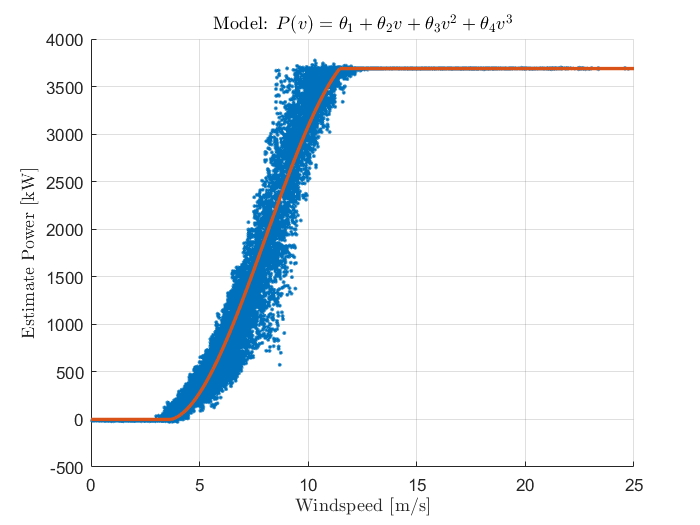

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [ones((cutout_windspeed - cutin_windspeed)/density + 1, 1), windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];
Y_Hat_grid = PHIGrid * theta;

cutoutTDF = min(windspeedGrid(Y_Hat_grid >= saturationValue));
cutinTDF = max(windspeedGrid(Y_Hat_grid <= 0 ));
windspeedGrid = [0 : density : 25]';

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, thirdDegreeFull_model(windspeedGrid, theta, cutoutTDF, saturationValue, cutinTDF), 'LineWidth',2);
grid on;
title('Model: $P(v) = \theta_1 + \theta_2 v + \theta_3 v^2 + \theta_4 v^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

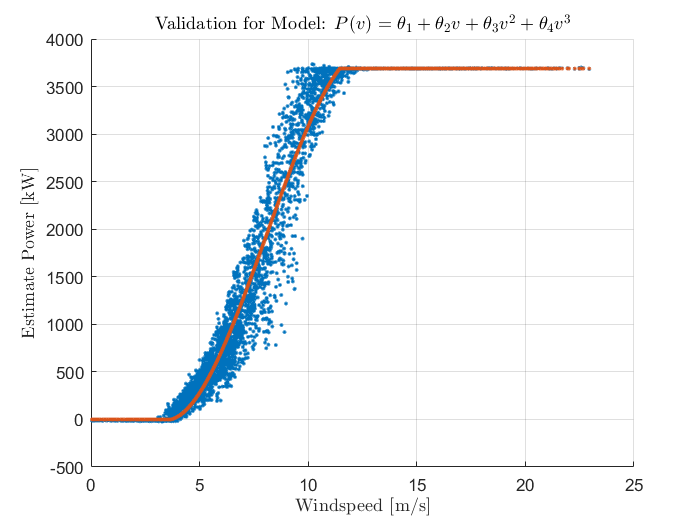

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
scatter(validationSet.windspeed, thirdDegreeFull_model(validationSet.windspeed, theta, cutoutTDF, saturationValue, cutinTDF), '.');
grid on;
title('Validation for Model: $P(v) = \theta_1 + \theta_2 v + \theta_3 v^2 + \theta_4 v^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

cubicModel_fourth.parameters = theta;
cubicModel_fourth.standardDeviation = sigma;
cubicModel_fourth.MSE = (1/length(Y_Hat))*sum((datainrange.windspeed - Y_Hat).^2);
cubicModel_fourth.SSR = sum((datainrange.windspeed - Y_Hat).^2);
cubicModel_fourth.FPE = ((length(Y_Hat) + length(theta))/(length(Y_Hat) - length(theta))) * cubicModel_fourth.SSR;
cubicModel_fourth.AIC = ((2*length(theta))/(length(Y_Hat)))*log(cubicModel_fourth.SSR);
cubicModel_fourth.MDL = ((log(length(Y_Hat))*length(theta)) / (length(Y_Hat))) * log(cubicModel_fourth.SSR);
cubicModel_fourth.ValidationSSR = sum((validationSet.power - Y_Hat_validation).^2);
cubicModel_fourth.WMAPE = sum(abs(validationSet.power - Y_Hat_validation))/sum(abs(validationSet.power));
cubicModel_fourth.NRMSE = sqrt(cubicModel_fourth.MSE / (max(validationSet.power) - min(validationSet.power)));

Prendo in considerazione modelli cubici di ordini diversi:


$$P\left(v\right)=\theta_1 v+\theta_2 v^{2\;} +\theta_3 v^3$$


PHI = [datainrange.windspeed, datainrange.windspeed.^2, datainrange.windspeed.^3];
[theta, sigma] = lscov(PHI, datainrange.power);
Y_Hat = PHI*theta;

cubicModel_third.parameters = theta;
cubicModel_third.standardDeviation = sigma;
cubicModel_third.MSE = (1/length(Y_Hat))*sum((datainrange.windspeed - Y_Hat).^2);
cubicModel_third.SSR = sum((datainrange.windspeed - Y_Hat).^2);

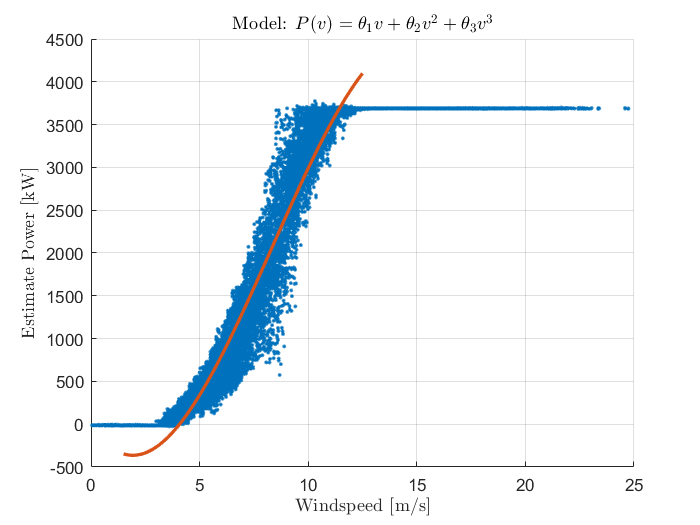

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, PHIGrid * theta, "LineWidth", 2);
grid on;
title('Model: $P(v) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

## Modello a doppio esponenziale

Il secondo tipo di modello preso in consideraizone è quello a doppio esponenziale. Il doppio esponenziale ha la forma classica del sigmoide che presenta anche la curva di potenza classica. Il modello a doppio esponenziale è della forma:


$$P(v) = e^{-e^ {\theta_1 v + \theta_2 v^2 + \theta_3 v^3}}$$
  

Attraverso un estrazione di due logaritmi naturali è possibile ricondurre a un modello lineare nei parametri:


$$log(-log(P(v))) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$$


In questo caso l'intervallo di valori presi in considerazione è quello al di sotto della velocità di cut-out del vento. Necessario prendere solo i valori di potenza strettamente positivi a causa della presenza del logaritmo. Inoltre $P\left(v\right)$ deve essere la funzione normalizzata, ovvero con valori $P\left(v\right)\in \left\lbrack 0,1\right\rbrack$, siccome il meno logaritmo deve essere definito.

cutout_windspeed = 15;
cutin_windspeed = 3;

datainrange = trainingSet(trainingSet.power > 0 & trainingSet.windspeed < cutout_windspeed , :);
scale = max(datainrange.power);
logData = [datainrange.windspeed, log(-log(datainrange.power*(1/scale)))];

PHI = [logData(:,1), logData(:,1).^2, logData(:,1).^3];
[theta, sigma] = lscov(PHI, logData(:,2));
Y_Hat = scale * exp(-exp(PHI*theta));

doubleExponentialModel.parameters = theta;
doubleExponentialModel.standardDeviation = sigma;
doubleExponentialModel.MSE = (1/length(Y_Hat))*sum((datainrange.windspeed - Y_Hat).^2);
doubleExponentialModel.SSR = sum((datainrange.windspeed - Y_Hat).^2);

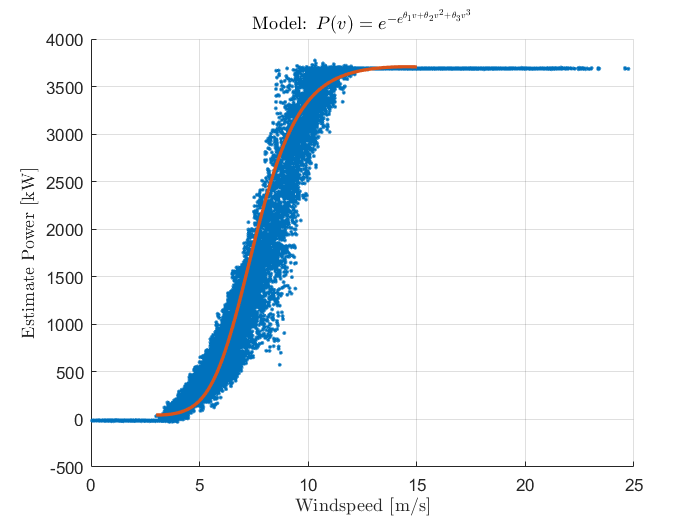

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, scale * exp(-exp(PHIGrid * theta)) ,"LineWidth", 2);
grid on;
title('Model: $P(v) = e^{-e^{\theta_1 v + \theta_2 v^2 + \theta_3 v^3}}$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

## Funzione Logistica

La funzione logistica ha la caratteristica forma a sigmoide simile alla forma della curva di potenza da modellizzare:


$$P\left(v\right)=\frac{\theta_1 }{1+\theta_2 e^{-\theta_3 v} }$$


E' un modello non linrare, quindi va applicato un algoritmo iterativo come quello di Gauss-Newton con variante di Levenberg-Marquardt siccome le matrici appaiono singolari. (Non ho trovato un modo di aggiungerlo o specificarla, allora ho trovato un compromesso dato dal fatto che avevo una buona inizializzazione dal lavoro fatto dall'algoritmo di discesa del gradiente su Python).

Il fattore di Levenberg-Marquardt $\lambda$ (`dampingLM`) determina il comportamento dell'algoritmo. Un valore ridotto corrisponde ad un comportamento simile al metodo di Gauss-Newton, mentre un valore elevato corrisponde a un comportamento simile al metodo di discesa del gradiente. Il valore viene adattato ad ogni iterazione, incrementandolo se la precedente iterazione ha prodotto una riduzione limitata della funzione obiettivo, o diminuendolo in caso di rapida diminuzione.

Qui viene usato un fattore moltiplicativo di aggiornamento $\nu \;$(`dampingUpdate`). Data un iterazione, si valuta quale smorzamento tra $\lambda \;$e $\frac{\lambda }{\nu \;}$ produce un miglioramento della funzione di costo.

theta_k = [3.7746e3, 6.8820e4 , 1.74]';
iterations = 300;

normalization_factor = 1 / max(trainingSet.windspeed);
normalized_power = normalization_factor * trainingSet.power;
model_order = length(theta_k);
dampingLM = 8e-5;
dampingUpdate = 2;

for i = 1:iterations
    [phi_1, phi_2, phi_3] = gradient_logistic(trainingSet.windspeed, theta_k);
    PHI_k = [phi_1, phi_2, phi_3];
    Y_tilde = normalized_power - normalization_factor * logistic(trainingSet.windspeed, theta_k);
    
    theta_tilde = inv( PHI_k' * PHI_k + dampingLM * eye(model_order) ) * (PHI_k' * Y_tilde);
    theta_tilde2 = inv( PHI_k' * PHI_k + (dampingLM/dampingUpdate) * eye(model_order) ) * (PHI_k' * Y_tilde);
    cost1 = sum((trainingSet.power - logistic(trainingSet.windspeed, theta_k + theta_tilde)).^2);
    cost2 = sum((trainingSet.power - logistic(trainingSet.windspeed, theta_k + theta_tilde2)).^2);
    
    if(cost1 > cost2)
        dampingLM = dampingLM/dampingUpdate;
        theta_tilde = theta_tilde2;
    end
    
    theta_k = theta_k + theta_tilde;
end

theta = theta_k;

Linearizzo attorno ai parametri $\hat{\theta \;}$ trovati così da poter trovare una stima approssimata della variaza dei parametri dopo aver trovato una stima della variaza dell'errore.

[phi_1, phi_2, phi_3] = gradient_logistic(trainingSet.windspeed, theta_k);
PHI_k = [phi_1, phi_2, phi_3];
sigma_hat = (1/(length(Y_Hat) - length(theta))) * sum( (trainingSet.power - logistic(trainingSet.windspeed, theta)).^2);

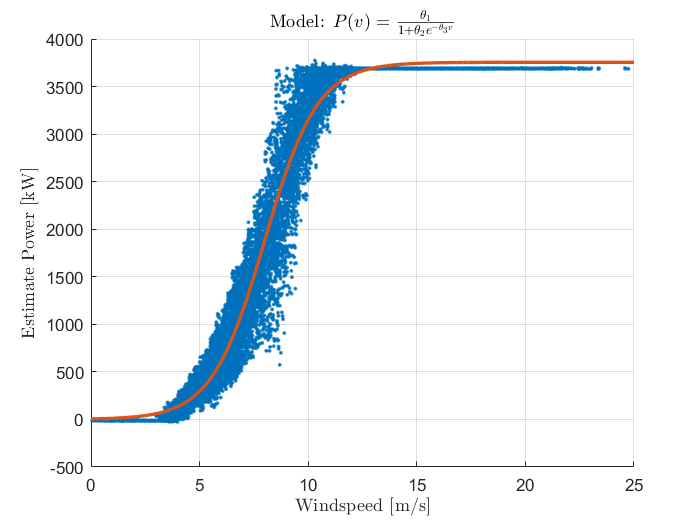

windspeedGrid = [0:0.01:25];
figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, logistic(windspeedGrid, theta), 'LineWidth', 2);
grid on;
title('Model: $P(v) = \frac{\theta_1}{1 + \theta_2 e^{- \theta_3 v}}$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

Previsione sui dati di validazione:

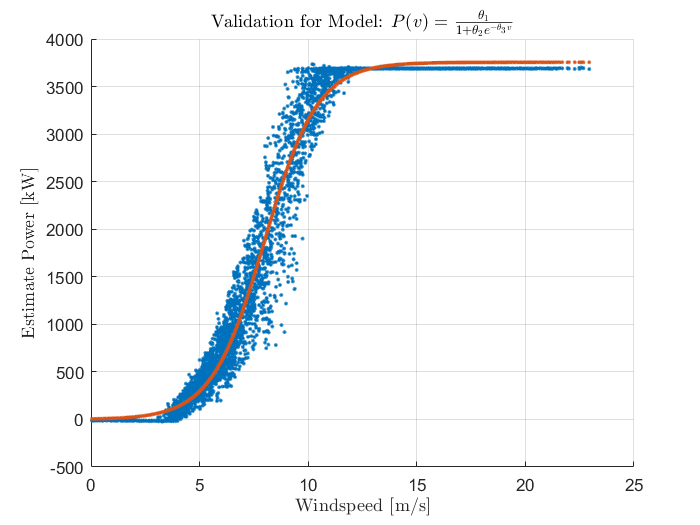

Y_Hat_validation = logistic(validationSet.windspeed, theta);

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
scatter(validationSet.windspeed, Y_Hat_validation, '.');
grid on;
title('Validation for Model: $P(v) = \frac{\theta_1}{1 + \theta_2 e^{- \theta_3 v}}$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

Aggiungo ora i parametri e le metriche alla struttura:

logisticModel.parameters = theta;
logisticModel.standardDeviation = sqrt(diag(sigma_hat * inv(PHI_k' * PHI_k + 11e-5 * eye(model_order))));
logisticModel.MSE = (1/length(Y_Hat)) * sum( (trainingSet.power - logistic(trainingSet.windspeed, theta)).^2 );
logisticModel.SSR = sum( (trainingSet.power - logistic(trainingSet.windspeed, theta)).^2 );